Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Alpha\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.5 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


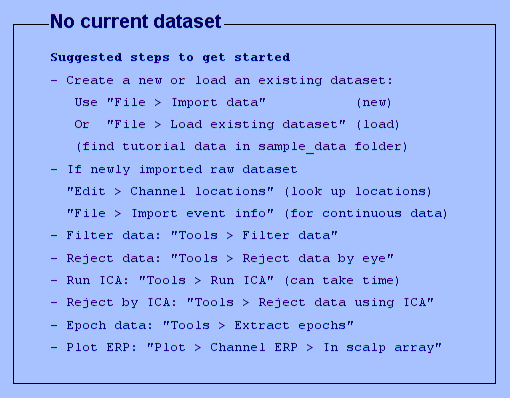

You are using the latest version of EEGLAB.


clear
load RawData.mat
eeglab

Data = EEG_data([1:64],:);
EOG = EEG_data([65:68],:);

% promediación clásica señal original
Ltrial = 60*sampling_rate

Ltrial = 61440

ntrials = floor(double(EEGPoints)/Ltrial)

ntrials = 5

trials = zeros(ntrials, 64,Ltrial );
for i=0:ntrials-1
    trials(i+1,:,:) = Data(:, [i*Ltrial+1:(i+1)*Ltrial]);
end
meanEEG = mean(trials, 1);

meanEEG = meanEEG(:,:,1) =

   -1.6570   -0.8544   -1.8746   -0.9872   -0.4193  -10.8068   -1.7415    0.2396   -8.4957   -2.6289   -2.9524    0.3018   -5.9262   -2.6298   -3.8516   -1.9013   -0.4364   -3.5834    2.5794    0.7333   -1.1648    2.1044    4.2614   13.8240    4.3851    3.9533    4.7967    4.7360    5.6230    0.4825    1.0283    0.8233   -2.5021   -4.8828   -3.3805   -5.9673   -0.1190   -5.1498    3.0597    5.6594    3.0844   -0.9942    7.5268   -3.8499   -2.4716    1.3623    1.1298    3.0887   -3.8802   -4.0280   -1.3644   -0.6227   -4.7781    4.2052    0.1177   -0.2522   -0.0955    0.5746    1.2678    4.2940   -3.8936    3.5393    2.8703    7.4992


meanEEG(:,:,2) =

   -2.3510   -1.6129   -2.6602   -0.6906   -0.0525  -10.0488   -1.8324    0.3472   -7.5374   -1.9777   -2.7095    0.4704   -5.4382   -1.0944   -3.7436   -3.7709    1.1258   -2.9910    3.1336    0.4844   -0.8419    2.5019    3.5944   11.8058    3.7023    3.8732    3.8989    3.0296    4.6095    0.3335    0.9211 

[~, sh1, sh2] = size(meanEEG);

sh1 = 64

sh2 = 61440

meanEEG = reshape(meanEEG, sh1, sh2);

meanEEG = 	1.0e+03 *

   -0.0017   -0.0024   -0.0029   -0.0030   -0.0029   -0.0029   -0.0026   -0.0020   -0.0017   -0.0017   -0.0020   -0.0029   -0.0042   -0.0053   -0.0060   -0.0063   -0.0061   -0.0056   -0.0054   -0.0057   -0.0060   -0.0061   -0.0063   -0.0062   -0.0054   -0.0044   -0.0039   -0.0040   -0.0042   -0.0039   -0.0039   -0.0048   -0.0063   -0.0071   -0.0069   -0.0057   -0.0039   -0.0018   -0.0003   -0.0002   -0.0011   -0.0019   -0.0020   -0.0017   -0.0018   -0.0022   -0.0028   -0.0036   -0.0048   -0.0057
   -0.0009   -0.0016   -0.0014   -0.0008   -0.0008   -0.0010   -0.0006    0.0005    0.0012    0.0012    0.0003   -0.0011   -0.0023   -0.0027   -0.0025   -0.0025   -0.0027   -0.0028   -0.0027   -0.0026   -0.0025   -0.0025   -0.0030   -0.0039   -0.0045   -0.0046   -0.0049   -0.0053   -0.0047   -0.0026   -0.0002    0.0002   -0.0016   -0.0034   -0.0033   -0.0018    0.0003    0.0023    0.0033    0.0030    0.0021    0.0017    0.0017    0.0015    0.0012    0.0009    0.0008    0.0

Ts = 1/sampling_rate;
t = 0:Ltrial-1

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


t = double(t)*Ts

t =          0    0.0010    0.0020    0.0029    0.0039    0.0049    0.0059    0.0068    0.0078    0.0088    0.0098    0.0107    0.0117    0.0127    0.0137    0.0146    0.0156    0.0166    0.0176    0.0186    0.0195    0.0205    0.0215    0.0225    0.0234    0.0244    0.0254    0.0264    0.0273    0.0283    0.0293    0.0303    0.0312    0.0322    0.0332    0.0342    0.0352    0.0361    0.0371    0.0381    0.0391    0.0400    0.0410    0.0420    0.0430    0.0439    0.0449    0.0459    0.0469    0.0479


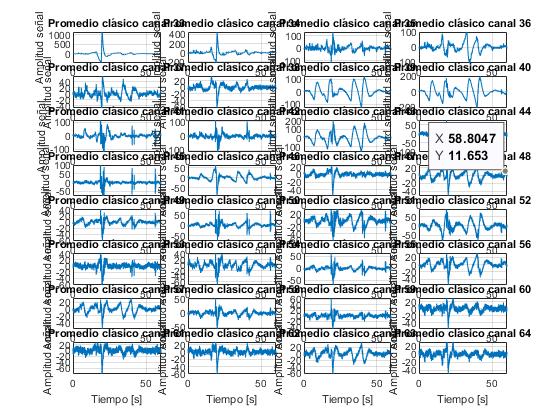

figure()
for i=33:64
    subplot(ceil(32/4),4,i-32)
    plot(t, meanEEG(i,:)')
    title(['Promedio clásico canal ' num2str(i)])
    ylabel('Amplitud señal')
    xlabel('Tiempo [s]')
    grid
    axis tight
end

% EOG
Ts = 1/sampling_rate;
t2 = 0:EEGPoints-1

t2 = 1×334848 uint32 row vector
    0    1    2    3    4    5    6    7    8    9   10   11   12   13   14   15   16   17   18   19   20   21   22   23   24   25   26   27   28   29   30   31   32   33   34   35   36   37   38   39   40   41   42   43   44   45   46   47   48   49


t2 = double(t2)*Ts

t2 =          0    0.0010    0.0020    0.0029    0.0039    0.0049    0.0059    0.0068    0.0078    0.0088    0.0098    0.0107    0.0117    0.0127    0.0137    0.0146    0.0156    0.0166    0.0176    0.0186    0.0195    0.0205    0.0215    0.0225    0.0234    0.0244    0.0254    0.0264    0.0273    0.0283    0.0293    0.0303    0.0312    0.0322    0.0332    0.0342    0.0352    0.0361    0.0371    0.0381    0.0391    0.0400    0.0410    0.0420    0.0430    0.0439    0.0449    0.0459    0.0469    0.0479


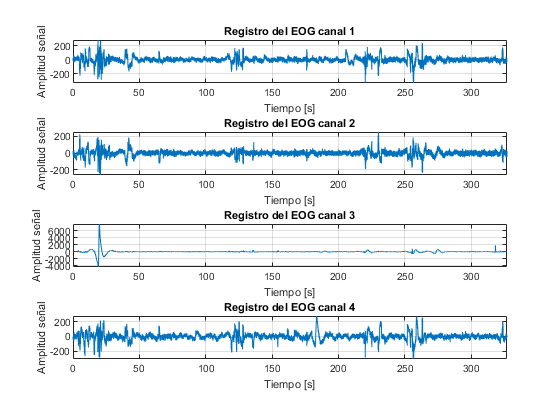

figure()
for i=1:4
    subplot(4,1,i)
    plot(t2, EOG(i,:)')
    title(['Registro del EOG canal ' num2str(i)])
    ylabel('Amplitud señal')
    xlabel('Tiempo [s]')
    grid
    axis tight
end

% ICA
B = jader(Data, 30);

jade -> Looking for 30 sources
jade -> Removing the mean value
jade -> Whitening the data
jade -> Estimating cumulant matrices
jade -> Initialization of the diagonalization
jade -> Contrast optimization by joint diagonalization
jade -> Sweep #0
jade -> Sweep #1
jade -> Sweep #2
jade -> Sweep #3
jade -> Sweep #4
jade -> Sweep #5
jade -> Sweep #6
jade -> Sweep #7
jade -> Sweep #8
jade -> Sweep #9
jade -> Sweep #10
jade -> Sweep #11
jade -> Sweep #12
jade -> Sweep #13
jade -> Sweep #14
jade -> Sweep #15
jade -> Sweep #16
jade -> Sweep #17
jade -> Sweep #18
jade -> Sweep #19
jade -> Sweep #20
jade -> Sweep #21
jade -> Sweep #22
jade -> Sweep #23
jade -> Sweep #24
jade -> Sweep #25
jade -> Sweep #26
jade -> Sweep #27
jade -> Sweep #28
jade -> Sweep #29
jade -> Sweep #30
jade -> Total of 7641 Givens rotations
jade -> Sorting the components
jade -> Fixing the signs


S = B*Data;

% Componentes
Ts = 1/sampling_rate;
t2 = 0:EEGPoints-1

t2 = 1×334848 uint32 row vector
    0    1    2    3    4    5    6    7    8    9   10   11   12   13   14   15   16   17   18   19   20   21   22   23   24   25   26   27   28   29   30   31   32   33   34   35   36   37   38   39   40   41   42   43   44   45   46   47   48   49


t2 = double(t2)*Ts

t2 =          0    0.0010    0.0020    0.0029    0.0039    0.0049    0.0059    0.0068    0.0078    0.0088    0.0098    0.0107    0.0117    0.0127    0.0137    0.0146    0.0156    0.0166    0.0176    0.0186    0.0195    0.0205    0.0215    0.0225    0.0234    0.0244    0.0254    0.0264    0.0273    0.0283    0.0293    0.0303    0.0312    0.0322    0.0332    0.0342    0.0352    0.0361    0.0371    0.0381    0.0391    0.0400    0.0410    0.0420    0.0430    0.0439    0.0449    0.0459    0.0469    0.0479


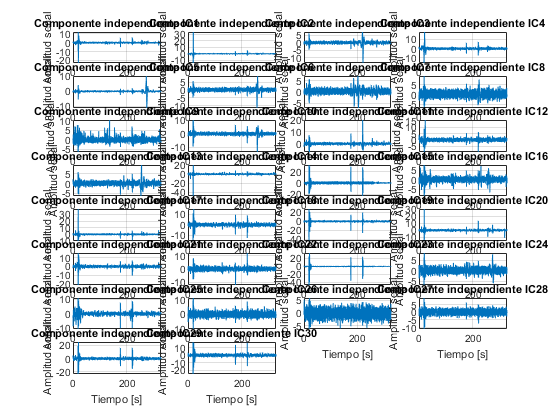

figure()
for i=1:30
    subplot(ceil(30/4),4,i)
    plot(t2, S(i,:)')
    title(['Componente independiente IC' num2str(i)])
    ylabel('Amplitud señal')
    xlabel('Tiempo [s]')
    grid
    axis tight
end

% canonical correlations
L1 = size(S)

L1 =           30      334848


L1 = L1(1)

L1 = 30

L2 = size(EOG)

L2 =            4      334848


L2 = L2(1)

L2 = 4

rr = zeros(L1,L2);
for i=1:L1
    for j=1:L2
        [Wx, Wy, r] = cca_b (EOG(j,:), S(i,:));
        rr(i,j) = r;
    end
end
rr

rr =     0.0086    0.1419    0.6038    0.1433
    0.0209    0.0033    0.5369    0.0112
    0.0411    0.0429    0.0834    0.0357
    0.0984    0.2293    0.4564    0.1278
    0.0570    0.1395    0.1091    0.0243
    0.4205    0.1408    0.0886    0.3603
    0.0958    0.1378    0.0419    0.0574
    0.1414    0.0499    0.0194    0.1234
    0.0951    0.0864    0.0848    0.1301
    0.0839    0.0128    0.0619    0.1069


mean_rr = mean(rr, 2)

mean_rr =     0.2244
    0.1431
    0.0507
    0.2280
    0.0825
    0.2525
    0.0832
    0.0835
    0.0991
    0.0664


% Mejores componentes
N = 28

N = 28

a = zeros(1,N);
meanpj_c = mean_rr

meanpj_c =     0.2244
    0.1431
    0.0507
    0.2280
    0.0825
    0.2525
    0.0832
    0.0835
    0.0991
    0.0664


for i=1:N
    [minpj, idx] = min(meanpj_c);
    a(i) = idx;
    meanpj_c(idx) = max(meanpj_c)+1;
end
a

a =     22    30    29    27     3    17    18    26    19    10    23    13    20    24     5     7     8    25    15    11     9    21    14    28     2    12     1     4


% Recontrucción con N componentes
clean_data = icaproj(Data, B, a);

% promediación clásica señal limpia
Ltrial = 60*sampling_rate;
ntrials = floor(double(EEGPoints)/Ltrial);
trials = zeros(ntrials, 64,Ltrial );
for i=0:ntrials-1
    trials(i+1,:,:) = Data(:, [i*Ltrial+1:(i+1)*Ltrial]);
end
meanEEG = mean(trials, 1);
[~, sh1, sh2] = size(meanEEG);
meanEEG = reshape(meanEEG, sh1, sh2);

Ts = 1/sampling_rate;
t = 0:Ltrial-1

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


t = double(t)*Ts

t =          0    0.0010    0.0020    0.0029    0.0039    0.0049    0.0059    0.0068    0.0078    0.0088    0.0098    0.0107    0.0117    0.0127    0.0137    0.0146    0.0156    0.0166    0.0176    0.0186    0.0195    0.0205    0.0215    0.0225    0.0234    0.0244    0.0254    0.0264    0.0273    0.0283    0.0293    0.0303    0.0312    0.0322    0.0332    0.0342    0.0352    0.0361    0.0371    0.0381    0.0391    0.0400    0.0410    0.0420    0.0430    0.0439    0.0449    0.0459    0.0469    0.0479


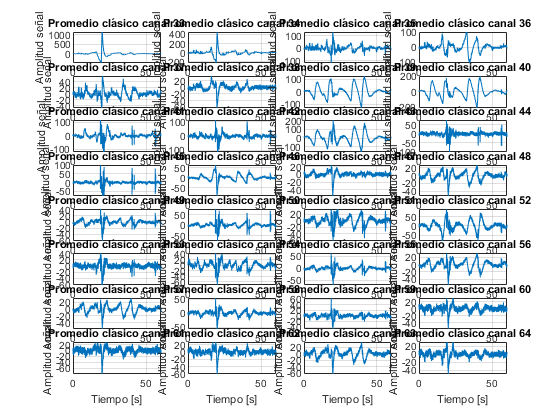

figure()
for i=33:64
    subplot(ceil(32/4),4,i-32)
    plot(t, meanEEG(i,:)')
    title(['Promedio clásico canal ' num2str(i)])
    ylabel('Amplitud señal')
    xlabel('Tiempo [s]')
    grid
    axis tight
end

N = 5;
a = zeros(1,N);
meanpj_c = mean_rr;
for i=1:N
    [minpj, idx] = min(meanpj_c);
    a(i) = idx;
    meanpj_c(idx) = max(meanpj_c)+1;
end
a

a =     22    30    29    27     3


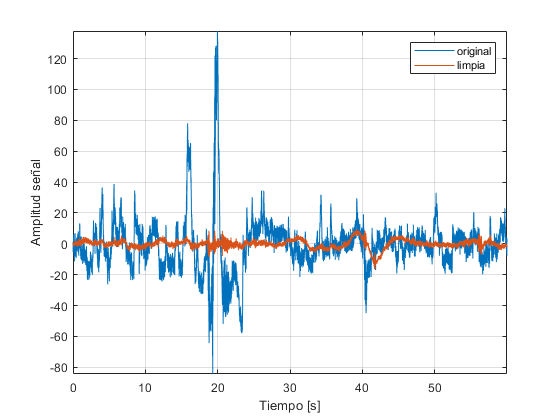

clean_data = icaproj(Data, B, a);
Ltrial = 60*sampling_rate;
ntrials = floor(double(EEGPoints)/Ltrial);
trials = zeros(ntrials, 64,Ltrial );
for i=0:ntrials-1
    trials(i+1,:,:) = clean_data(:, [i*Ltrial+1:(i+1)*Ltrial]);
end
mean_clean_data = mean(trials, 1);
[~, sh1, sh2] = size(mean_clean_data);
mean_clean_data = reshape(mean_clean_data, sh1, sh2);

figure()
plot(t, meanEEG(2,:)')
hold on
plot(t, mean_clean_data(2,:)')
hold off
xlim([17 25])
legend('original','limpia')
ylabel('Amplitud señal')
xlabel('Tiempo [s]')
grid
axis tight

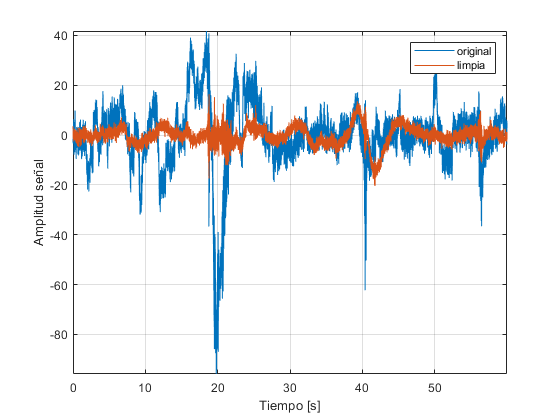


figure()
plot(t, meanEEG(7,:)')
hold on
plot(t, mean_clean_data(7,:)')
hold off
xlim([8 26])
legend('original','limpia')
ylabel('Amplitud señal')
xlabel('Tiempo [s]')
grid
axis tight

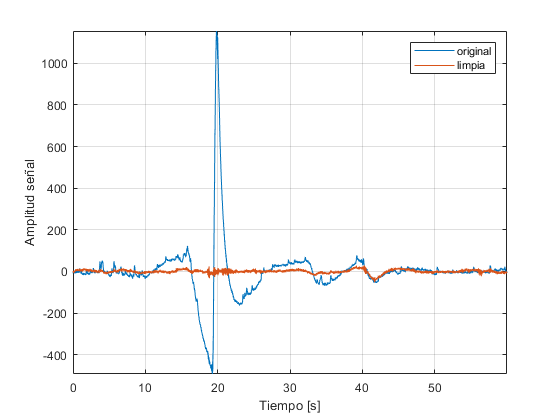



figure()
plot(t, meanEEG(33,:)')
hold on
plot(t, mean_clean_data(33,:)')
hold off
xlim([9 30])
legend('original','limpia')
ylabel('Amplitud señal')
xlabel('Tiempo [s]')
grid
axis tight

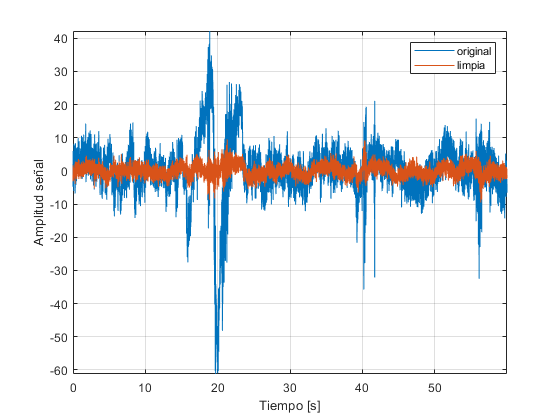



figure()
plot(t, meanEEG(53,:)')
hold on
plot(t, mean_clean_data(53,:)')
hold off
xlim([17 25])
legend('original','limpia')
ylabel('Amplitud señal')
xlabel('Tiempo [s]')
grid
axis tight

% Optimizado para quitar atifacts relacionados con el canal 3 del EOG
N = 27;
a = zeros(1,N);
meanpj_c = rr(:,3)

meanpj_c =     0.6038
    0.5369
    0.0834
    0.4564
    0.1091
    0.0886
    0.0419
    0.0194
    0.0848
    0.0619


for i=1:N
    [minpj, idx] = min(meanpj_c);
    a(i) = idx;
    meanpj_c(idx) = max(meanpj_c)+1;
end
a

a =     22    26    16    27    29    25     8    17    30    28    11    23     7    13    18    24    10    20     3     9     6    19     5    21    15    12    14


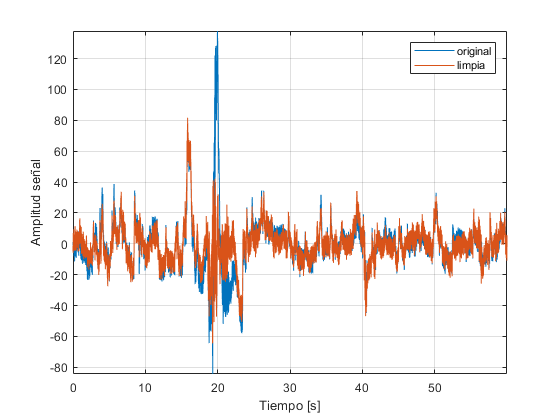

clean_data = icaproj(Data, B, a);
Ltrial = 60*sampling_rate;
ntrials = floor(double(EEGPoints)/Ltrial);
trials = zeros(ntrials, 64,Ltrial );
for i=0:ntrials-1
    trials(i+1,:,:) = clean_data(:, [i*Ltrial+1:(i+1)*Ltrial]);
end
mean_clean_data = mean(trials, 1);
[~, sh1, sh2] = size(mean_clean_data);
mean_clean_data = reshape(mean_clean_data, sh1, sh2);

figure()
plot(t, meanEEG(2,:)')
hold on
plot(t, mean_clean_data(2,:)')
hold off
xlim([17 25])
legend('original','limpia')
ylabel('Amplitud señal')
xlabel('Tiempo [s]')
grid
axis tight

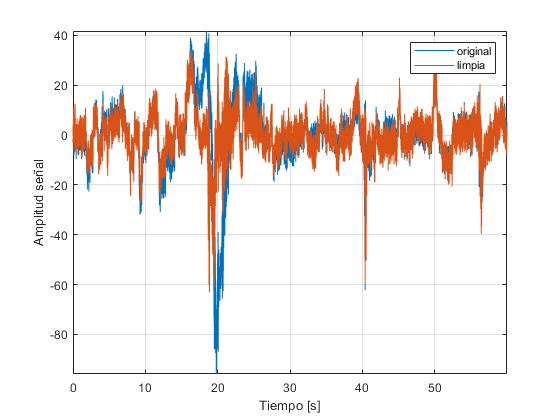



figure()
plot(t, meanEEG(7,:)')
hold on
plot(t, mean_clean_data(7,:)')
hold off
xlim([8 26])
legend('original','limpia')
ylabel('Amplitud señal')
xlabel('Tiempo [s]')
grid
axis tight

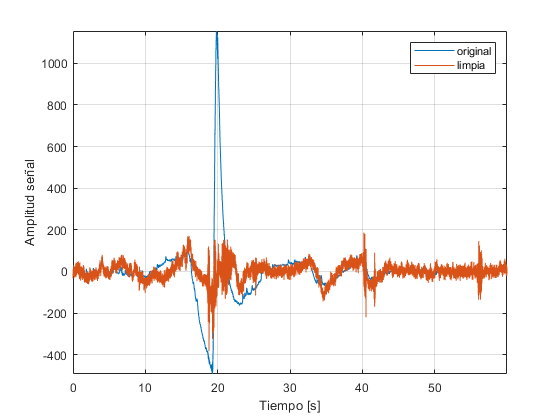



figure()
plot(t, meanEEG(33,:)')
hold on
plot(t, mean_clean_data(33,:)')
hold off
xlim([9 30])
legend('original','limpia')
ylabel('Amplitud señal')
xlabel('Tiempo [s]')
grid
axis tight

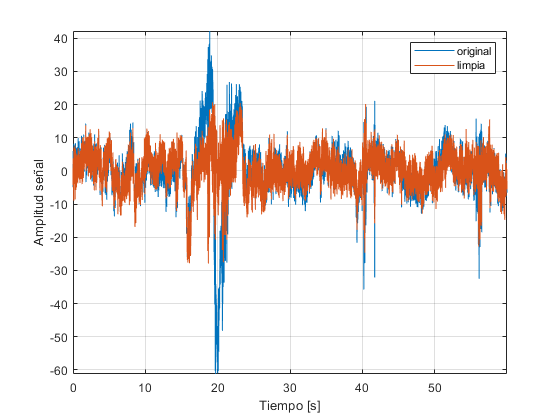



figure()
plot(t, meanEEG(53,:)')
hold on
plot(t, mean_clean_data(53,:)')
hold off
xlim([17 25])
legend('original','limpia')
ylabel('Amplitud señal')
xlabel('Tiempo [s]')
grid
axis tight

function [Wx, Wy, r] = cca_b(X,Y)
% CCA calculate canonical correlations
%
% [Wx Wy r] = cca(X,Y) where Wx and Wy contains the canonical
% correlation vectors as columns and r is a vector with
% corresponding canonical correlations. The correlations are
% sorted in descending order. X and Y are matrices where
% each column is a sample. Hence, X and Y must have
% the same number of columns.
%
% Example: If X is M*K and Y is N*K there are L=MIN(M,N) solutions.
% Wx is then M*L, Wy is N*L and r is L*1.
%
%
% 2000 Magnus Borga, Linkpings universitet
% --- Calculate covariance matrices ---
z = [X;Y];
C = cov(z.');
sx = size(X,1);
sy = size(Y,1);
Cxx = C(1:sx, 1:sx) + 10^(-8)*eye(sx);
Cxy = C(1:sx, sx+1:sx+sy);
Cyx = Cxy';
Cyy = C(sx+1:sx+sy, sx+1:sx+sy) + 10^(-8)*eye(sy);
invCyy = inv(Cyy);
% --- Calcualte Wx and r ---
[Wx,r] = eig(inv(Cxx)*Cxy*invCyy*Cyx); % Basis in X
r = sqrt(real(r)); % Canonical correlations
% --- Sort correlations ---
V = fliplr(Wx); % reverse order of eigenvectors
r = flipud(diag(r)); % extract eigenvalues anr reverse their orrer
[r,I]= sort((real(r))); % sort reversed eigenvalues in ascending order
r = flipud(r); % restore sorted eigenvalues into descending order
for j = 1:length(I)
    Wx(:,j) = V(:,I(j)); % sort reversed eigenvectors in ascending order
end
Wx = fliplr(Wx); % restore sorted eigenvectors into descending order
% --- Calcualte Wy ---
Wy = invCyy*Cyx*Wx; % Basis in Y
Wy = Wy./repmat(sqrt(sum(abs(Wy).^2)),sy,1); % Normalize Wy

end